# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 4ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

clear;clc;close all

## Άσκηση 1 : Στοχαστικές Διαδικασίες 

### Υλοποίηση Στοχαστικής Διαδικασίας

K = 100;
n = -50:200;
A = rand(K,1) - 1/2;



mask = ((n > 0) - (n - 100 > 0));


x = A* mask ;% ones(length(mask),length(mask));

mask2D = repmat(mask,K,1);

x = A .* mask2D;


mean_val = mean(x);

Acor = x'*x/K;
Sd = 20*log10(fftshift(abs(fft2(Acor))));

### Γραφικές Παραστάσεις

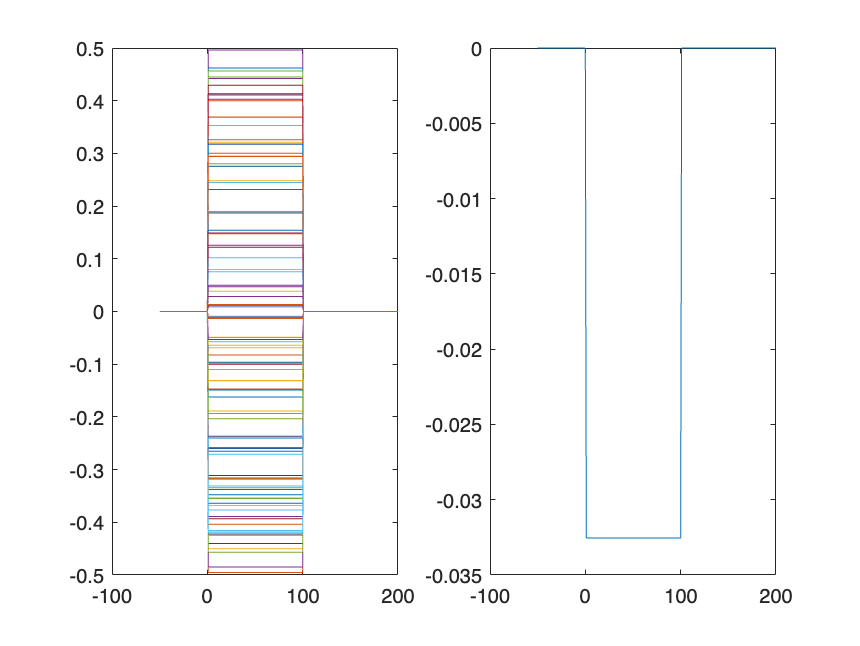

figure;
subplot(121);plot(n,x);
subplot(122);plot(n,mean_val);

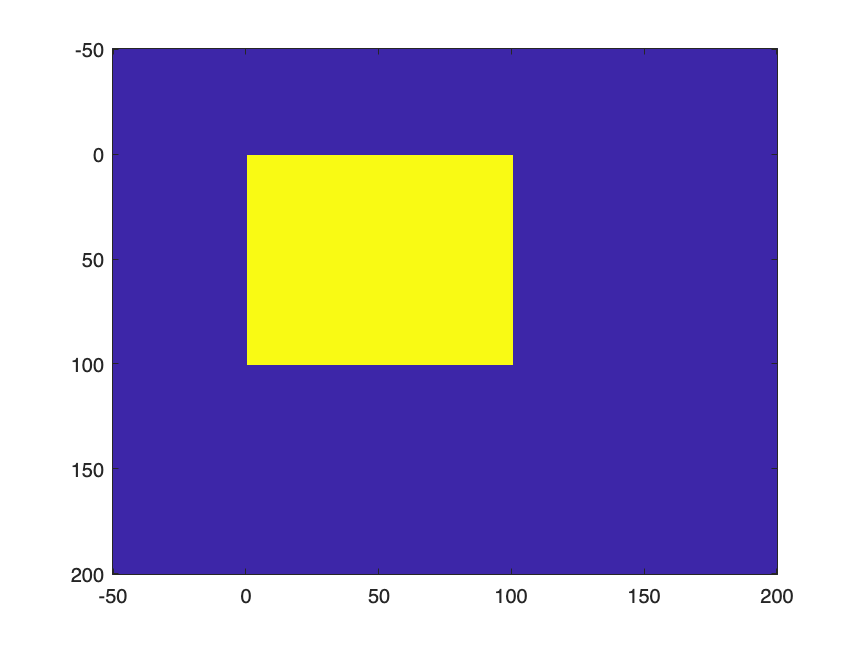


figure; imagesc(n,n,Acor)

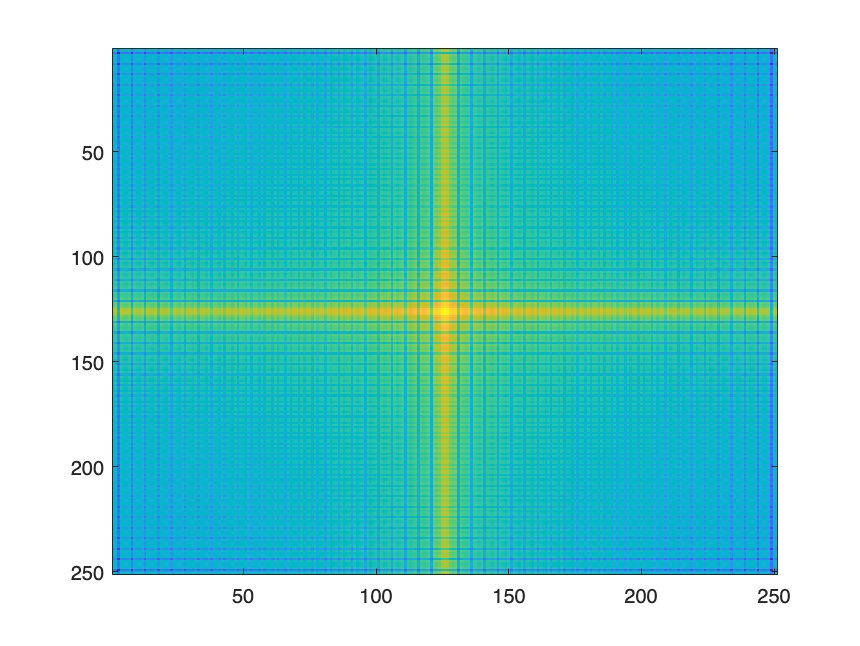


figure; imagesc(Sd)

## Άσκηση 2 : Στοχαστικές Διαδικασίες 

### Υλοποίηση Στοχαστικής Διαδικασίας

K = 100;
n = -50:200;
A = randn(K,1);



mask = ((n > 0) - (n - 100 > 0));


x = A* mask ;% ones(length(mask),length(mask));

mask2D = repmat(mask,K,1);

x = A .* mask2D;


mean_val = mean(x);

Acor = x'*x/K;
Sd = 20*log10(fftshift(abs(fft2(Acor))));

### Γραφικές Παραστάσεις

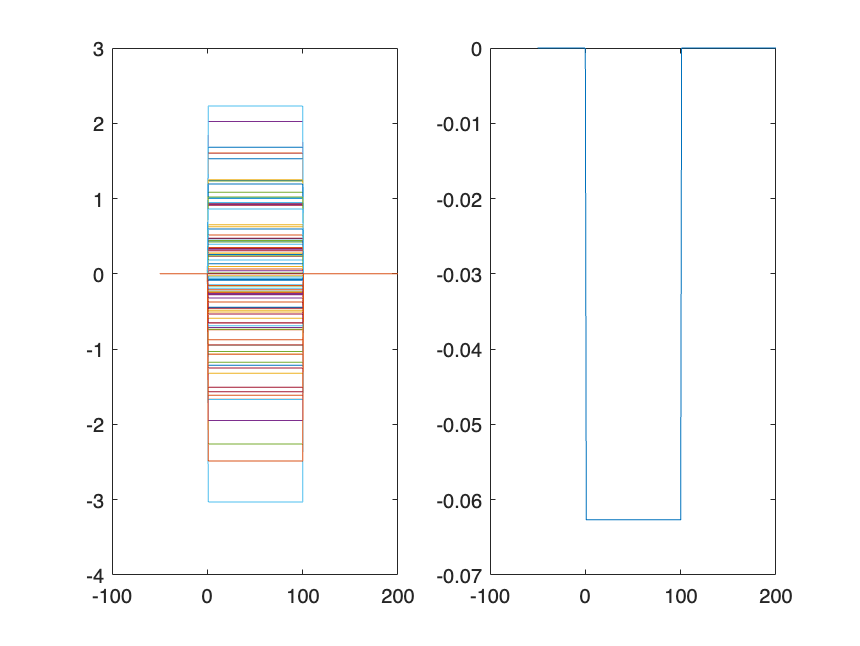

subplot(121);plot(n,x);
subplot(122);plot(n,mean_val);


figure; imagesc(n,n,Acor)


figure; imagesc(Sd)

## Άσκηση 3 : Βασικοί Νόμοι της Στατιστικής

### Αποθορυβοποίηση μέσω του Νόμου των Μεγάλων Αριθμών

load eye

#### Εφαρμογή του Νόμου των Μεγάλων Αριθμών

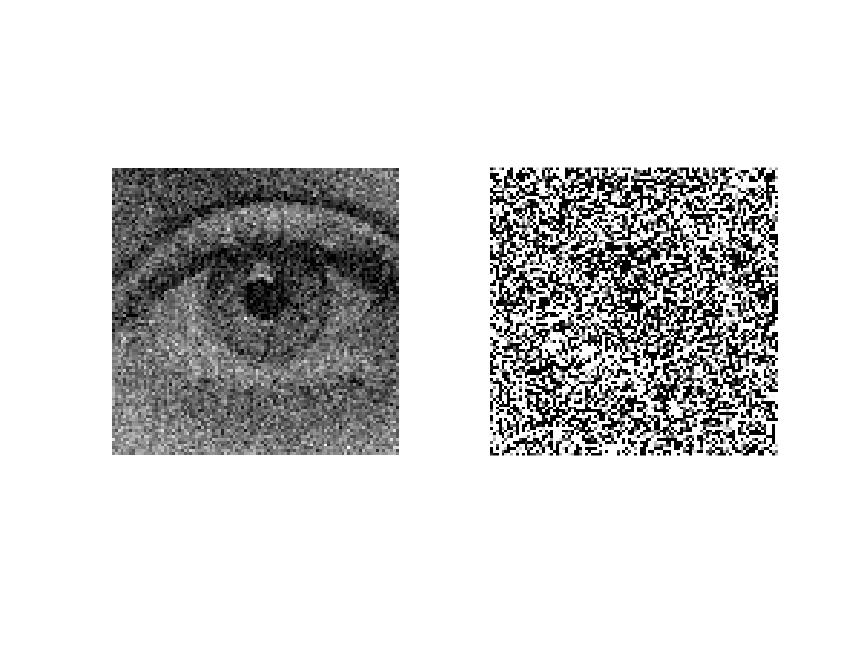

approx = zeros(size(I(:,:,1)));

for counter = 1 : 100
    approx = approx + I(:, :, counter);
end

approx = approx/100;

figure;
subplot(121);imshow(approx/max(approx(:)));
subplot(122);imshow(I(:,:,1))

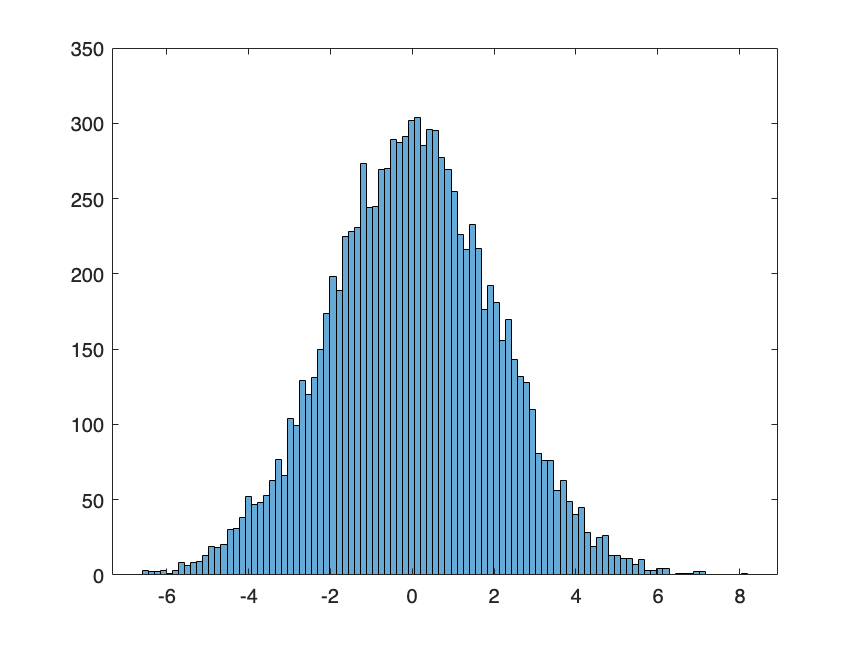

%for a single image
noise = I(:,:,1) - approx;
figure;
histogram(noise, 100);

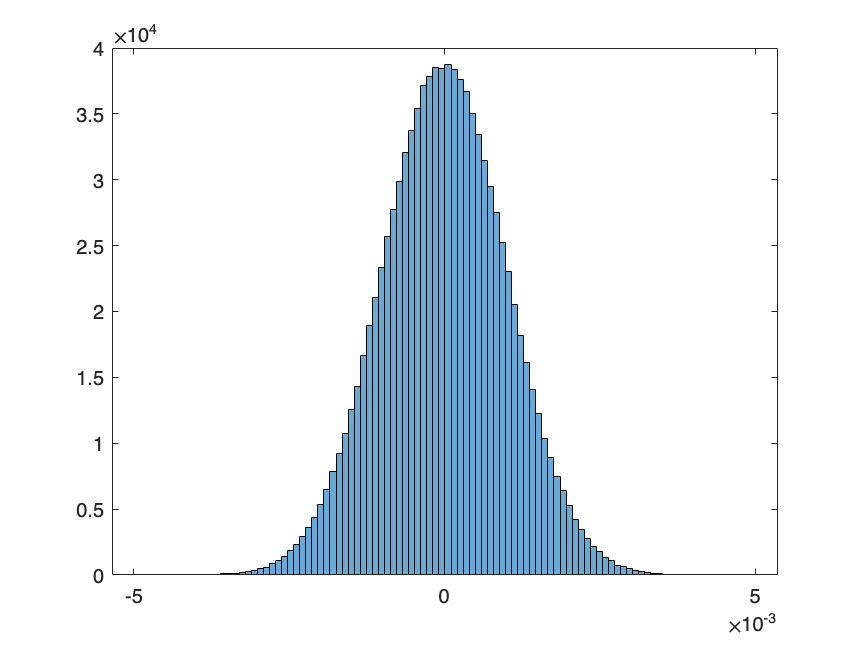


m = mean(noise(:));
s = std(noise(:));

I2 = zeros(size(I(:,:,1)));
for counter = 1 : 100
    I2 =  I2 + I(:, :, counter) -  approx;
end

%divide by sigma
I2 = I2/(10*s);


m=mean(I(:)); %flatten I to a vector by I(:)
s = std(I(:));
figure

samples = (I(:)-m)/(s*sqrt(100^3));
histogram(samples, 100); %should be gaussian N(0,1)

## Άσκηση 4 : FIR Φίλτρο Wiener

### Φόρτωση Βίντεο και Επιλογή Πίξελ 

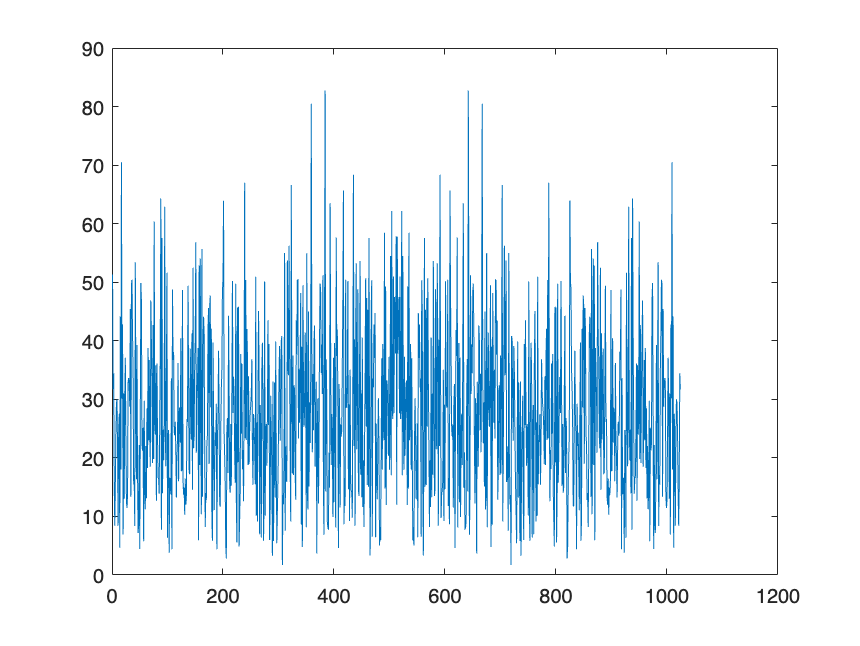

n=0:1000;
phi = rand(1)*2*pi;
s = sin(0.25*n+phi);

w = randn(1,length(n));
v = filter(1,[1,-0.6],w); %colored noise

%check 
figure;plot(abs(fftshift(fft(w,2^10))))

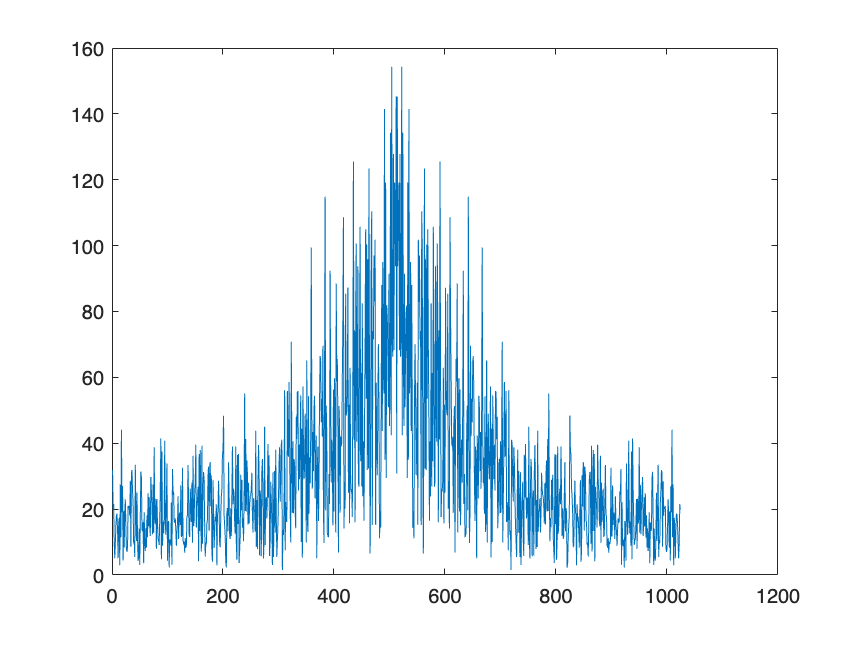


figure;plot(abs(fftshift(fft(v,2^10))))


x = s+w;


%rn = w.*v;
v0 = v;
w0 = w;

%find the cross correlation
rsx=[0;0];
for n=2:length(v)
    rsx(1)=rsx(1)+v(n)*w(n);
    rsx(2)=rsx(2)+v(n-1)*w(n);
end
rsx=rsx/(length(v)-1);


%find the autocorrelation
v1 = v0;
v2 = v0;

v1(end) = [];
v2(1) = [];

X = [v2;v1];
Rxx = X*X'/length(v1);


hW =  rsx' * inv(Rxx);

%hW = hW;

%corr_vector = xcorr(v, w);

%here find the filter hW
%hW =[];

%apply to colored noise to make it white again
w_hat = filter(hW,1,v);

%check to see the whitening
figure;plot(abs(fftshift(fft(w_hat,2^10))))

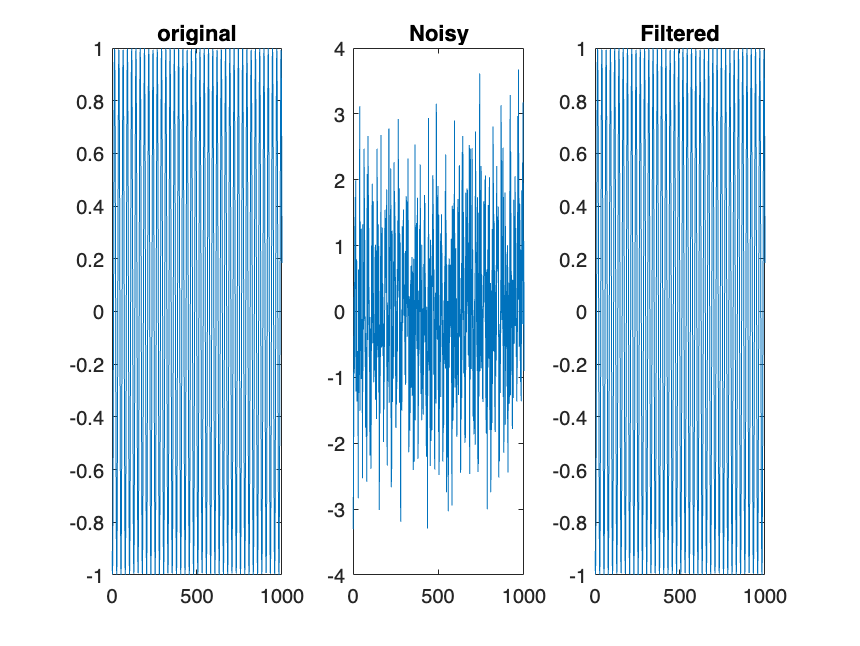



norm(w-w_hat); %to minimize
x_hat = x-w_hat;

subplot(131);plot(s);title('original');
subplot(132);plot(x);title('Noisy');
subplot(133);plot(x_hat);title('Filtered');



rms_noise = norm(x-s);
rms_filtered_noise = norm(x-s-w_hat);